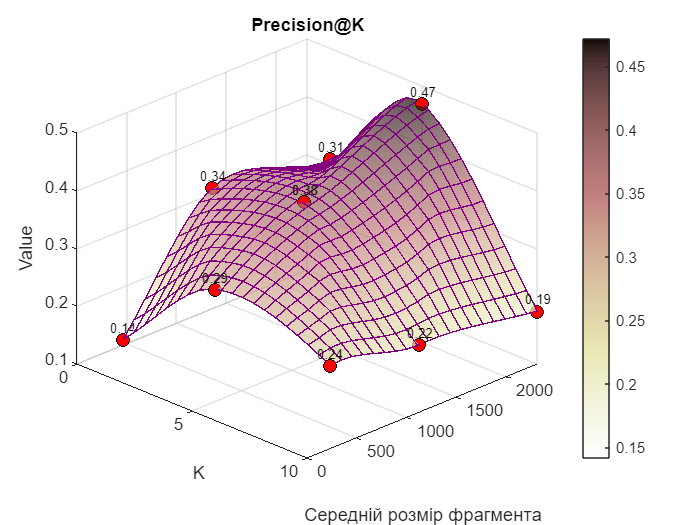

% -------------------------------------------------------------------------
% MATLAB: 3D-поверхні Precision@K і MRR із ще меншою щільністю сітки
% Використано griddata(...,'cubic') для плавної інтерполяції, surf + mesh
% -------------------------------------------------------------------------

% 1. Оригінальні дані
k_values    = [1, 5, 10];          % K
size_values = [227, 1129, 2312];   % Середній розмір фрагмента

Z1 = [ 0.1420, 0.2943, 0.2437;      % Precision@K
       0.3422, 0.3833, 0.2164;
       0.3077, 0.4687, 0.1909 ];

Z2 = [ 0.3273, 0.3653, 0.3921;      % MRR
       0.4256, 0.4321, 0.4301;
       0.3970, 0.4192, 0.4167 ];

% 2. Побудова дискретної сітки 3×3 (щоб потім показати вихідні точки)
[K_orig, S_orig] = meshgrid(k_values, size_values);

% 3. Створюємо ще менш густу «щільну» сітку, наприклад 20×20
kq = linspace(min(k_values),   max(k_values),   20);    % 20 точок від 1 до 10
sq = linspace(min(size_values), max(size_values), 20);   % 20 точок від 227 до 2312
[Kq, Sq] = meshgrid(kq, sq);

% 4. Інтерполяція «cubic» для плавного вигину поверхні
Z1_interp = griddata(K_orig, S_orig, Z1, Kq, Sq, 'cubic');  % Precision@K
Z2_interp = griddata(K_orig, S_orig, Z2, Kq, Sq, 'cubic');  % MRR

% -------------------------------------------------------------------------
% 5. Precision@K (зменшена щільність сітки)
figure;
surf(Kq, Sq, Z1_interp, ...
     'FaceAlpha', 0.7, ...       % трохи прозорості
     'EdgeColor','none', ...     % прибираємо ребра заливки
     'FaceColor','interp');      % інтерполяція кольору
hold on;
mesh(Kq, Sq, Z1_interp, ...
     'EdgeColor',[0.5, 0, 0.5], ...  % темно-рожеві ребра
     'FaceColor','none', ...
     'LineWidth',0.8);               % трохи товщі лінії для кращої видимості

% Наносимо початкові 3×3 точки
scatter3(K_orig(:), S_orig(:), Z1(:), ...
         60, 'r', 'filled', ...
         'MarkerFaceColor','r', ...
         'MarkerEdgeColor','k');

% Додаємо підписи значень біля початкових точок
for i = 1:numel(Z1)
    text(K_orig(i), S_orig(i), Z1(i) + 0.02, ...
         sprintf('%.2f', Z1(i)), ...
         'FontSize', 8, 'HorizontalAlignment', 'center', ...
         'Color', 'k');
end

xlabel('K');
ylabel('Середній розмір фрагмента');
zlabel('Value');
title('Precision@K');
colormap(flipud(pink));   % рожеві відтінки
colorbar;
view(45, 30);
hold off;

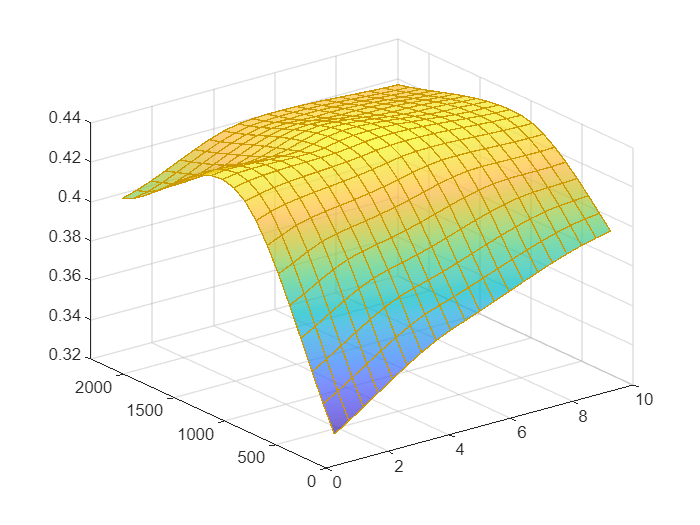

Error using scatter3
Error setting property 'MarkerFaceColor' of class 'Scatter':
Invalid color name or hexadecimal color code. Valid names include: 'red', 'green', 'blue', 'cyan', 'magenta', 'yellow', 'black', 'white', and 'none'. Valid hexadecimal color codes consist of '#' followed by three or six hexadecimal digits.


% -------------------------------------------------------------------------
% 6. MRR (зменшена щільність сітки)
figure;
surf(Kq, Sq, Z2_interp, ...
     'FaceAlpha', 0.7, ...
     'EdgeColor','none', ...
     'FaceColor','interp');
hold on;
mesh(Kq, Sq, Z2_interp, ...
     'EdgeColor',[0.8, 0.6, 0], ...  % темно-золоті ребра
     'FaceColor','none', ...
     'LineWidth',0.8);

scatter3(K_orig(:), S_orig(:), Z2(:), ...
         60, 'm', 'filled', ...
         'MarkerFaceColor','orange', ...
         'MarkerEdgeColor','k');

for i = 1:numel(Z2)
    text(K_orig(i), S_orig(i), Z2(i) + 0.02, ...
         sprintf('%.2f', Z2(i)), ...
         'FontSize', 8, 'HorizontalAlignment', 'center', ...
         'Color', 'k');
end

xlabel('K');
ylabel('Середній розмір фрагмента');
zlabel('Value');
title('MRR');
colormap(summer);        % золотисто-зелені відтінки
colorbar;
view(45, 30);
hold off;

% -------------------------------------------------------------------------
% 7. Precision@K та MRR разом (ще менш щільна сітка)
figure;
% Precision@K
surf(Kq, Sq, Z1_interp, ...
     'FaceAlpha', 0.4, ...
     'EdgeColor','none', ...
     'FaceColor','interp');
hold on;
mesh(Kq, Sq, Z1_interp, ...
     'EdgeColor',[0.5, 0, 0.5], ...
     'FaceColor','none', ...
     'LineWidth',0.5);

% MRR
surf(Kq, Sq, Z2_interp, ...
     'FaceAlpha', 0.4, ...
     'EdgeColor','none', ...
     'FaceColor','interp');
mesh(Kq, Sq, Z2_interp, ...
     'EdgeColor',[0.8, 0.6, 0], ...
     'FaceColor','none', ...
     'LineWidth',0.5);

% Початкові точки обох метрик
scatter3(K_orig(:), S_orig(:), Z1(:), ...
         40, 'r', 'filled');   % для Precision@K
scatter3(K_orig(:), S_orig(:), Z2(:), ...
         40, 'm', 'filled');   % для MRR

xlabel('K');
ylabel('Середній розмір фрагмента');
zlabel('Value');
title('Precision@K та MRR разом');
legend({'Precision@K (поверхня)','Precision@K (ребра)', ...
        'MRR (поверхня)','MRR (ребра)', ...
        'Точки Precision@K','Точки MRR'}, ...
       'Location','northoutside','Orientation','horizontal');
view(40, 25);
hold off;
